clc;
clear;
close all;

## =================================================

## PART 1: VEHICLE PARAMETERS

## =================================================

m = 1800;                 % Vehicle mass (kg)
g = 9.81;                 % Gravity (m/s^2)
Crr = 0.01;               % Rolling resistance coefficient
rho = 1.225;              % Air density (kg/m^3)
Cd = 0.29;                % Drag coefficient
A = 2.2;                  % Frontal area (m^2)

delta = 0.08;             % Rotational Mass factor
m_eq = m*(1 + delta);

r_wheel = 0.3;            % Wheel radius (m)

## =================================================

## PART 2: IMPORT UDDS DRIVE CYCLE

## =================================================

udds_data = readtable("uddsdc.csv");

t = udds_data.UDDS;       % Time (s)
v_mph = udds_data.Var2;   % Speed (mph)

v = v_mph * 0.44704;      % Convert mph → m/s

dt = mean(diff(t));

a = [diff(v)/dt; 0];      % Acceleration

% Acceleration limits
a_max = 3;
a_min = -4;

a(a>a_max) = a_max;
a(a<a_min) = a_min;

## =================================================

## PART 3: LONGITUDINAL FORCES

## =================================================

gear_ratio = 9;

omega_wheel = v / r_wheel;
omega = omega_wheel * gear_ratio;

F_rr   = m * g * Crr;
F_aero = 0.5 * rho * Cd * A .* v.^2;
F_acc  = m_eq .* a;

theta = deg2rad(0);
F_rg = m*g*sin(theta);

F_total = F_rr + F_aero + F_acc + F_rg;

## =================================================

## PART 4: WHEEL MECHANICAL POWER

## =================================================

P_wheel = F_total .* v;

eta_tire = 0.95;
P_wheel = P_wheel / eta_tire;

## =================================================

## PART 5: MOTOR + REGEN LIMITS

## =================================================

T_motor_max = 250;
T_regen_max = 120;
P_motor_max = 80e3;

v_min_regen = 1.5;

eta_drivetrain = 0.95;

P_mech = zeros(size(P_wheel));

omega_base = P_motor_max / T_motor_max;

for i = 1:length(P_wheel)

    if P_wheel(i) > 0

        if omega(i) <= omega_base
            T_avail = T_motor_max;
        else
            T_avail = P_motor_max / omega(i);
        end

        P_avail = T_avail * omega(i);

        P_mech(i) = min(P_wheel(i), P_avail);

    elseif P_wheel(i) < 0 && v(i) > v_min_regen

        P_regen_limit = T_regen_max * omega(i);

        P_mech(i) = -min(abs(P_wheel(i)), P_regen_limit);

    else

        P_mech(i) = 0;

    end

end

% drivetrain efficiency
P_mech = P_mech / eta_drivetrain;

## =================================================

## PART 6: DISTANCE & IDEAL ENERGY

## =================================================

E_Wh = trapz(t, P_mech) / 3600;

dist_km = trapz(t, v) / 1000;

E_Wh_per_km = E_Wh / dist_km;

## =================================================

## PART 7: MOTOR + INVERTER EFFICIENCY

## =================================================

omega_max = max(omega) + eps;

drive_eff = ones(size(P_mech));
regen_eff = ones(size(P_mech));

for i = 1:length(P_mech)

    if P_mech(i) > 0

        T_req = P_mech(i) / max(omega(i),eps);

        Tn = abs(T_req) / T_motor_max;

        on = omega(i) / omega_max;

        drive_eff(i) = 0.90 ...
            - 0.15*(1-on)^2 ...
            - 0.20*(Tn-0.6)^2;

        drive_eff(i) = min(max(drive_eff(i),0.75),0.92);

    elseif P_mech(i) < 0

        T_req = abs(P_mech(i)) / max(omega(i),eps);

        Tn = T_req / T_regen_max;

        on = omega(i) / omega_max;

        regen_eff(i) = 0.75 ...
            - 0.20*(1-on)^2 ...
            - 0.30*(Tn-0.5)^2;

        regen_eff(i) = min(max(regen_eff(i),0.55),0.80);

    end

end

## =================================================

## PART 8: BATTERY POWER FLOW

## =================================================

P_batt_disch_max = 90e3;
P_batt_char_max  = 40e3;

P_accessory = 900;

Batt_capacity = 50; % kWh

P_drive = zeros(size(P_mech));
P_regen = zeros(size(P_mech));

for i = 1:length(P_mech)

    if P_mech(i) > 0

        P_drive(i) = P_mech(i) / drive_eff(i);

        P_drive(i) = min(P_drive(i), P_batt_disch_max);

    elseif P_mech(i) < 0

        P_regen(i) = abs(P_mech(i)) * regen_eff(i);

        P_regen(i) = min(P_regen(i), P_batt_char_max);

    end

end

P_batt = P_drive - P_regen + P_accessory;

## =================================================

## PART 9: SOC MODEL

## =================================================

SOC = zeros(size(t));

SOC(1) = 0.80;

for i = 2:length(t)

    E_step_Wh = P_batt(i) * dt / 3600;

    SOC(i) = SOC(i-1) - E_step_Wh/(Batt_capacity*1000);

end

## =================================================

## PART 10: PLOTS

## =================================================

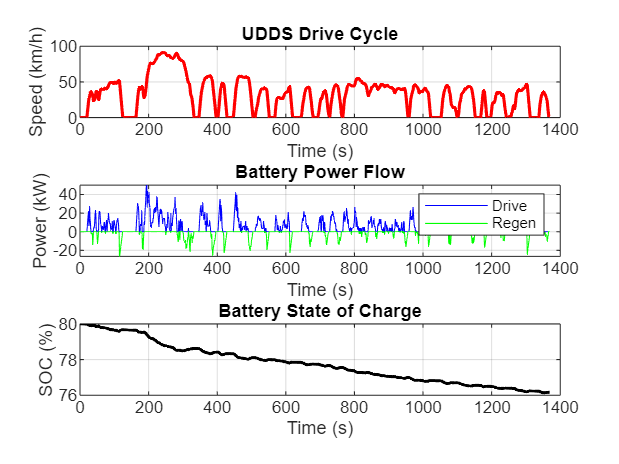

figure('Name','EV UDDS Simulation');

subplot(3,1,1)
plot(t,v*3.6,'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Speed (km/h)')
title('UDDS Drive Cycle')
grid on

subplot(3,1,2)
plot(t,P_drive/1000,'b'); hold on
plot(t,-P_regen/1000,'g')
xlabel('Time (s)')
ylabel('Power (kW)')
legend('Drive','Regen')
title('Battery Power Flow')
grid on

subplot(3,1,3)
plot(t,SOC*100,'k','LineWidth',1.5)
xlabel('Time (s)')
ylabel('SOC (%)')
title('Battery State of Charge')
grid on

## =================================================

## PART 11: FINAL RESULTS

## =================================================

E_drive_Wh = trapz(t,P_drive)/3600;

E_regen_Wh = trapz(t,P_regen)/3600;

E_batt_net = E_drive_Wh - E_regen_Wh;

E_brake_mech = trapz(t,abs(min(P_mech,0)))/3600;

regen_percentage = (E_regen_Wh/E_brake_mech)*100;

P_drive_max = max(P_drive)/1000;

P_regen_max = max(P_regen)/1000;

P_wheel_max = max(P_mech)/1000;

SOC_initial = SOC(1)*100;

SOC_final = SOC(end)*100;

SOC_delta = SOC_initial - SOC_final;

avg_speed_kmh = mean(v)*3.6;

## =================================================

## PRINT RESULTS

## =================================================

fprintf('\nVEHICLE & DRIVE CYCLE\n\n');


VEHICLE & DRIVE CYCLE




fprintf('Vehicle Mass\n: %.0f kg\n\n',m);

Vehicle Mass
: 1800 kg




fprintf('Total Distance Travelled\n: %.3f km\n\n',dist_km);

Total Distance Travelled
: 11.990 km




fprintf('Average Speed\n: %.2f km/h\n\n',avg_speed_kmh);

Average Speed
: 31.51 km/h




fprintf('Drive Cycle Duration\n: %.0f s\n\n',t(end));

Drive Cycle Duration
: 1369 s





fprintf('ENERGY CONSUMPTION\n\n');

ENERGY CONSUMPTION




fprintf('Wheel Mechanical Energy\n: %.2f Wh\n\n',E_Wh);

Wheel Mechanical Energy
: 815.62 Wh




fprintf('Battery Energy Drawn\n: %.2f Wh\n\n',E_drive_Wh);

Battery Energy Drawn
: 2222.15 Wh




fprintf('Battery Energy Regenerated\n: %.2f Wh\n\n',E_regen_Wh);

Battery Energy Regenerated
: 644.54 Wh




fprintf('Net Battery Energy Used\n: %.2f Wh\n\n',E_batt_net);

Net Battery Energy Used
: 1577.61 Wh




fprintf('Specific Energy Consumption\n: %.2f Wh/km\n\n',E_batt_net/dist_km);

Specific Energy Consumption
: 131.57 Wh/km





fprintf('POWER PERFORMANCE\n\n');

POWER PERFORMANCE




fprintf('Maximum Wheel Power\n: %.2f kW\n\n',P_wheel_max);

Maximum Wheel Power
: 43.32 kW




fprintf('Maximum Battery Drive Power\n: %.2f kW\n\n',P_drive_max);

Maximum Battery Drive Power
: 50.08 kW




fprintf('Maximum Regen Power\n: %.2f kW\n\n',P_regen_max);

Maximum Regen Power
: 26.51 kW





fprintf('REGENERATIVE BRAKING\n\n');

REGENERATIVE BRAKING




fprintf('Mechanical Braking Energy\n: %.2f Wh\n\n',E_brake_mech);

Mechanical Braking Energy
: 994.54 Wh




fprintf('Regen Energy Recovery\n: %.2f %%\n\n',regen_percentage);

Regen Energy Recovery
: 64.81 %





fprintf('BATTERY STATE OF CHARGE\n\n');

BATTERY STATE OF CHARGE




fprintf('Initial SOC\n: %.2f %%\n\n',SOC_initial);

Initial SOC
: 80.00 %




fprintf('Final SOC\n: %.2f %%\n\n',SOC_final);

Final SOC
: 76.16 %




fprintf('Net SOC Change\n: %.3f %%\n\n',SOC_delta);

Net SOC Change
: 3.840 %



## =================================================

## MOTOR TORQUE SPEED CHARACTERISTIC

## =================================================

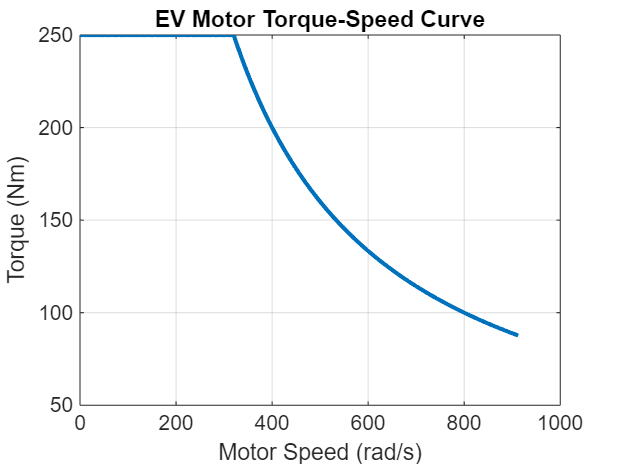

omega_range = linspace(0, max(omega)*1.2, 500);

T_motor = zeros(size(omega_range));

for i = 1:length(omega_range)

    if omega_range(i) <= omega_base
        T_motor(i) = T_motor_max;
    else
        T_motor(i) = P_motor_max / omega_range(i);
    end

end

figure

plot(omega_range, T_motor,'LineWidth',2);

xlabel('Motor Speed (rad/s)');
ylabel('Torque (Nm)');
title('EV Motor Torque-Speed Curve');

grid on;

## =================================================

## MOTOR EFFICIENCY MAP

## =================================================

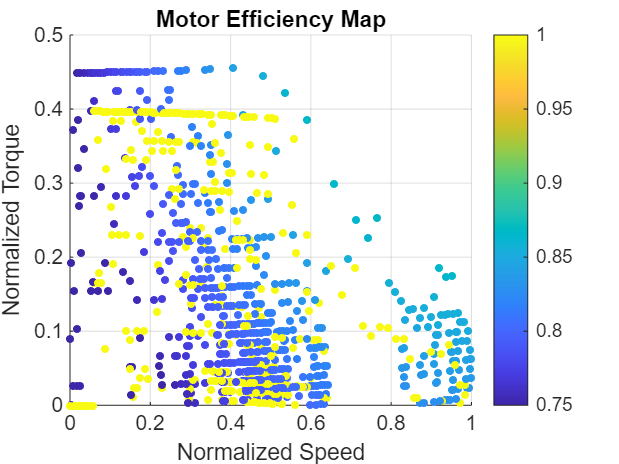

speed_norm = omega/omega_max;

torque = P_mech ./ max(omega,eps);

torque_norm = abs(torque)/T_motor_max;

figure

scatter(speed_norm, torque_norm, 15, drive_eff,'filled')

colorbar

xlabel('Normalized Speed');
ylabel('Normalized Torque');

title('Motor Efficiency Map');

grid on;

## =================================================

## ENERGY FLOW ANALYSIS

## =================================================

E_accessory = trapz(t, ones(size(t))*P_accessory)/3600;

fprintf('\nENERGY FLOW ANALYSIS\n\n');


ENERGY FLOW ANALYSIS




fprintf('Drive Energy From Battery : %.2f Wh\n',E_drive_Wh);

Drive Energy From Battery : 2222.15 Wh



fprintf('Recovered Regen Energy    : %.2f Wh\n',E_regen_Wh);

Recovered Regen Energy    : 644.54 Wh



fprintf('Accessory Consumption     : %.2f Wh\n',E_accessory);

Accessory Consumption     : 342.25 Wh



fprintf('Net Battery Consumption   : %.2f Wh\n',E_batt_net);

Net Battery Consumption   : 1577.61 Wh


## =================================================

## RANGE ESTIMATION

## =================================================

usable_SOC = 0.8 - 0.2;   % 80% to 20%

usable_energy = Batt_capacity * usable_SOC * 1000; % Wh

range_est = usable_energy / (E_batt_net/dist_km);

fprintf('\nESTIMATED EV RANGE\n\n');


ESTIMATED EV RANGE




fprintf('Estimated Range (UDDS Based) : %.1f km\n',range_est);

Estimated Range (UDDS Based) : 228.0 km
